above=1;
below=1;
difference=[];
itterations=10000;
outputs=[]


outputs =

     []



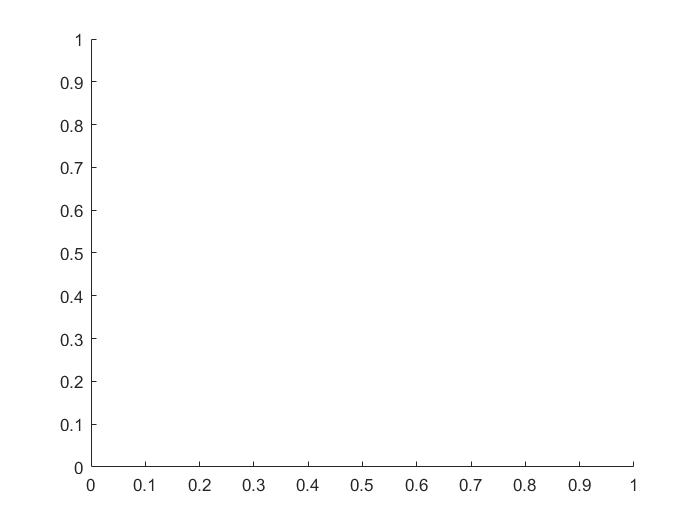

for i=1:itterations
    outputs(i)=asin(sin(f(i)));
    if(asin(sin(f(i)))>0)
        above=above+1;
    elseif(asin(sin(f(i)))<0)
        below=below+1;
    end
    difference(i)=above-below;
end
hold on

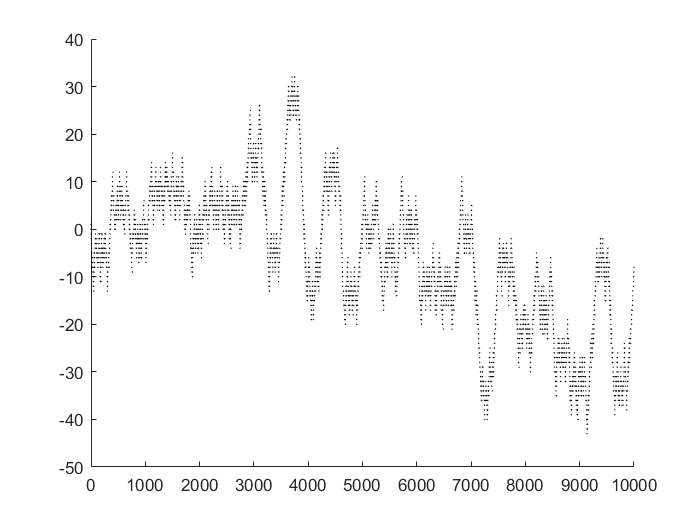

figure;
scatter(1:itterations,difference,1,'black','filled');
xlim([0 itterations])
hold off
hold on

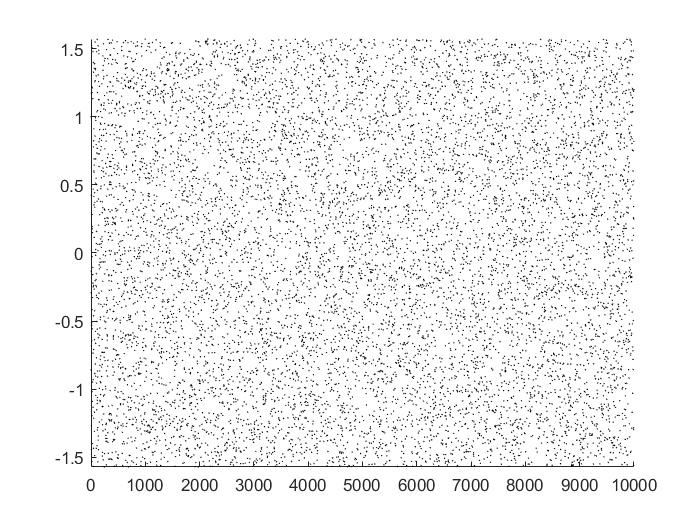

figure;
scatter(1:itterations,outputs,1,'black','filled');
xlim([0 itterations]);
ylim([-pi/2 pi/2]);
hold off

function y = f(x)
    y=x^2;
end